#                                             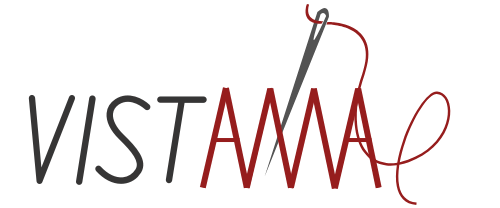

#  Vignetting Artifact Correction in Large Post-stitched Non-rectangular Tile maps

## Laboratory of Optical Bioimaging and Spectroscopy

copyright 

Anthony A Fung, Lingyan Shi, 2024, University of California San Diego 

All rights reserved

Input: You will need a single frame (2D) stitched grayscale image 

Instructions: Just press run. You may adjust variables such as "strel" and thresholds as needed in the tissue detection masking section

## Load image

% prompts user to select one or more image file types 
[fname, fpath] = uigetfile({'*.oir;*.oib;*.png;*.jpg;*.jpeg;*.tif;*.tiff;*.lif', 'Image Files (*.oir, *.png, *.jpg, *.jpeg, *.tif, *.tiff, *.lif)';
                                 '*.oir;*.oib', 'Olympus Bioformats (*.oir,*.oib)';
                                 '*.png', 'PNG Files (*.png)';
                                 '*.jpg;*.jpeg', 'JPEG Files (*.jpg, *.jpeg)';
                                 '*.tif;*.tiff', 'TIFF Files (*.tif, *.tiff)';
                                 '*.lif', 'Leica Image File (*.lif)'}, 'Select Grayscale Images', 'MultiSelect', 'off');
                              
% Check if the user canceled the file selection
if isequal(fname,0)
    return;
end
cd(fpath)
% Initialize variables
if ~iscell(fname)
    fname = {fname};
end
if ~iscell(fpath)
    fpath = {fpath};
end
fullFileName = fullfile(fpath, fname);
A=cell(1,length(fname));
[~, ~, fExt] = cellfun(@fileparts, fname, 'UniformOutput', false);
fExt = cellfun(@lower, fExt, 'UniformOutput', false);
numslices = zeros(length(fname), 1);

% Loop through files and import based on type
for i = 1:length(fname)
    ext = fExt{i}(2:end); % Remove the dot from the extension
    switch ext
        case {'oir', 'oib'}
            
            data=bfopen(fullFileName{i});
            series1 = data{1, 1};
            numslices(i) = size(series1, 1);
            data=bfOpen3DVolume(fullFileName{i});
            imgdat=data{1};
            A{i}=imgdat{1};                    
        case {'png', 'jpg', 'jpeg'}
            A{i} = imread(fullFileName{i});
            if ~ismatrix(A{i})
                errorMessage = sprintf('Error: Expected raw grayscale image. Your input will be converted'); 
                        uiwait(warndlg(errorMessage));
            end
            numslices(i) = 1;
        case {'tif', 'tiff'}
            info = imfinfo(fullFileName{i});
            numslices(i) = numel(info);
            if numslices(i) > 1
                A{i} = imread(fullFileName{i}, 'Index', 'all');
            else
                A{i} = imread(fullFileName{i});
            end
        case 'lif'
            bfreader = bfGetReader(fullFileName{i});
            A{i} = bfGetPlane(bfreader, 1); % Load the first plane as an example
            numslices(i) = bfreader.getSizeZ();
        case {'qptif','qptiff'}
            % Get image info
            infor = imfinfo(fullFileName{i});
            numslicestemp = numel(infor);
            tstack = Tiff(fullFileName{i});
        
            % Initialize data structure to hold slice dimensions
            dimensions = zeros(numslicestemp, 2);
            for ii = 1:numslicestemp
                dimensions(ii, :) = [infor(ii).Width, infor(ii).Height];
            end
            
            % Find unique dimensions and their slice indices
            [uniqueDims, ~, sliceGroups] = unique(dimensions, 'rows');
            
            % Find the largest resolution
            [~, maxIdx] = max(prod(uniqueDims, 2)); % Use product of width and height
            largestResolution = uniqueDims(maxIdx, :);
            
            % Find slices corresponding to the largest resolution
            largestSlices = find(sliceGroups == maxIdx);
        
            % Initialize a 3D array for the largest resolution slices
            numslices(i) = numel(largestSlices);
            largestDims = largestResolution;
            codex = zeros(largestDims(2), largestDims(1), numLargestSlices, 'like', tstack.read());
        
            warning('off', 'all'); % Suppress all TIFF warnings
            for j = 1:numslices(i)
                sliceIndex = largestSlices(j);
                tstack.setDirectory(sliceIndex);
                codex(:, :, j) = tstack.read();
            end
            warning('on', 'all'); % Re-enable warnings
            A{i}=codex;
        
         
        otherwise
            error('Unsupported file format: %s', ext);
    end
    
end

Reading series #1
    .....


Reading series #1
    .....



img=max(A{1},[],3);

## rescale the image to 0 and 1, retain original histogram range

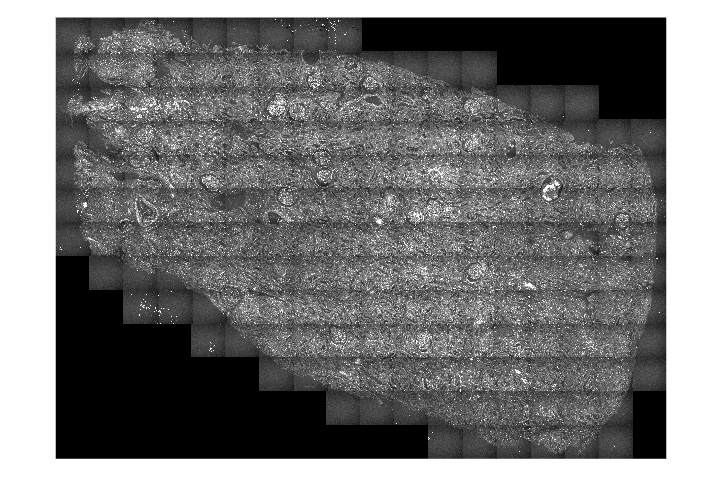


minimg=min(img(:));
origrange=double( max(img(:)) - minimg );
img = double(img - minimg) ./ origrange; % normalize the shifted data to 1
imshow(imadjust(rescale(img)));

## Remove NaN and INF pixels and make background uniform

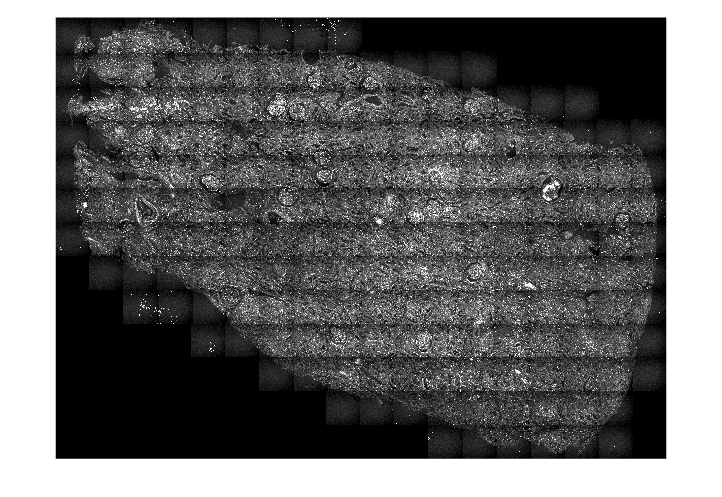

img(isinf(img)) = 0;
img(isnan(img)) = 0;


array = img;

% Flatten the array and remove zeros
flattened_array = array(array ~= 0);

% Sort the array
sorted_array = sort(flattened_array);

% Calculate the number of elements corresponding to the bottom 1%
num_elements = round(0.01 * numel(sorted_array));

% Find the threshold value for the bottom 1%
if num_elements > 0
    threshold_value = sorted_array(num_elements);
else
    threshold_value = sorted_array(1); % in case num_elements is less than 1, pick the smallest value
end

img(img==0)=threshold_value;

figure 
imshow(imadjust(rescale(img)))

## Isolate just the tissue

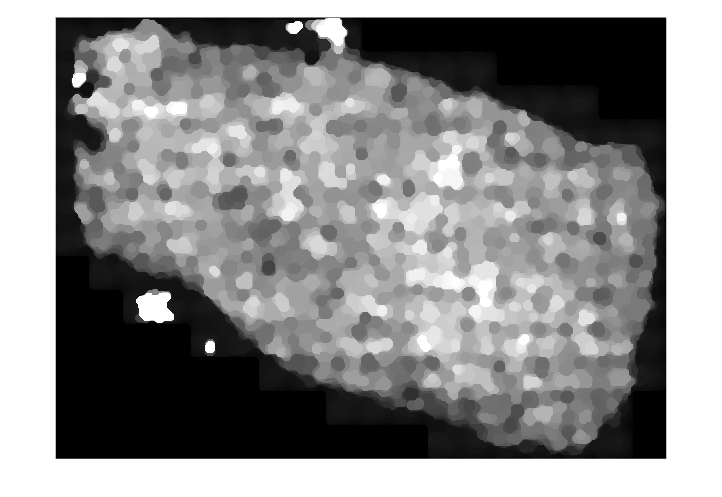

% find structures vs background
k=strel('disk',50); 
es=imclose(img,k); 
es=imopen(es,strel('disk',round(0.01*size(img,1)))); 
es=rescale(es);
figure
imshow(imadjust(imresize(es,0.5)))

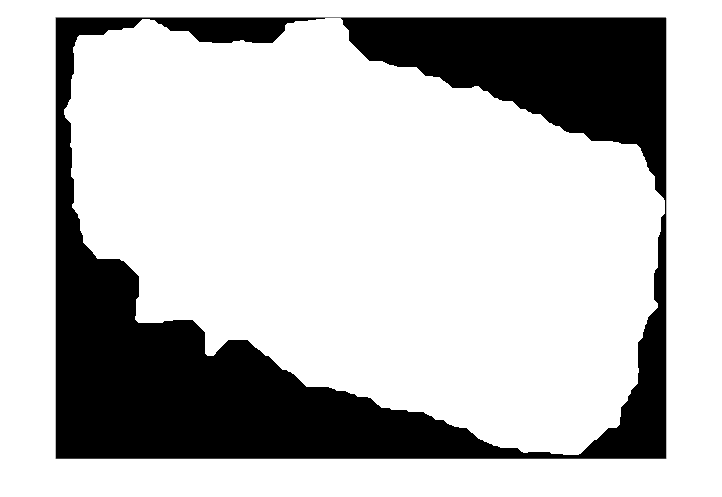


ks=imbinarize(es,0.1);
se=strel('disk',round(0.05*size(img,1)));
ks=imclose(ks,se);
ks=imfill(ks,'holes');
figure
imshow(ks)

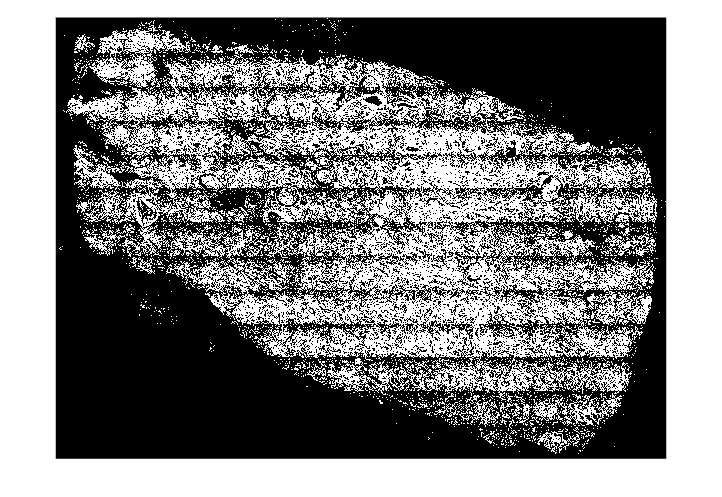

bgpxs=find(~ks);

% retain top 90% of pixels
lowcutoff1=mean(img(bgpxs));
lowcutoff2=prctile(img(:),90);
lowcutoff=1.05*mean([lowcutoff2;lowcutoff1]); % arbitrary, subject to change
mask=img;
mask(mask<lowcutoff)=0;
mask(mask>0)=1;

figure
imshow(mask)


clear es


## Remove bright areas temporarily so it doesn't affect tile detection

array=img(ks);

% Flatten the array and remove zeros
flattened_array = array(array ~= 0);

% Sort the array
sorted_array = sort(flattened_array);

% Calculate the number of elements corresponding to the bottom 1%
num_elements = round(0.99 * numel(sorted_array));

% Find the threshold value for the bottom 1%
if num_elements > 0
    threshold_value = sorted_array(num_elements);
else
    threshold_value = sorted_array(end); % in case num_elements is less than 1, pick the smallest value
end
imgNaN=img;
divyfactor=mean(flattened_array(:))/threshold_value;
% make a new image to store the brightspot so we can put them back later
brightspotsstore=zeros(size(imgNaN));
brightspotsstore(imgNaN>threshold_value)=imgNaN(imgNaN>threshold_value);
imgNaN(imgNaN>threshold_value)=imgNaN(imgNaN>threshold_value).*divyfactor; % sets bright pixels to the average value of the tissue's pixels so it doesn't throw off the analysis

normorigrange=threshold_value;
origrange = origrange*threshold_value;

clear ks

## Plot the horizontal and vertical intensity profiles to get an idea of the vignetting

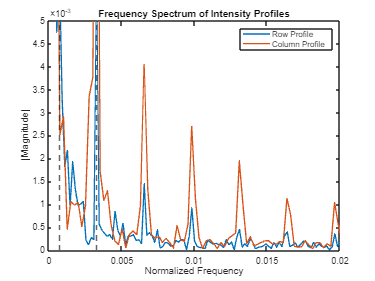



imgNaN(imgNaN == 0) = NaN;
avgRowIntensity = medfilt1(mean(imgNaN, 1, 'omitnan'),10); % Average across columns for each row, ignoring zeros
avgColIntensity = medfilt1(mean(imgNaN, 2, 'omitnan'),10); % Average across rows for each column, ignoring zeros
avgRowIntensity(1)=mean(avgRowIntensity(2));
avgColIntensity(1)=mean(avgColIntensity(2));

% Compute FFT and extract dominant frequencies for rows (vertical) and columns (horizontal)
[domRowFreq, domColFreq, freqRow, magRow, freqCol, magCol] = ...
    detectDominantFrequencies(avgRowIntensity, avgColIntensity);

% Plot frequency spectra for both profiles.
figure;
plot(freqRow, magRow, 'LineWidth', 1.5); hold on;
plot(freqCol, magCol, 'LineWidth', 1.5);
xline(domColFreq, '--', 'LineWidth', 1.5);
xline(domRowFreq, '--', 'LineWidth', 1.5);
hold off;
title('Frequency Spectrum of Intensity Profiles');
xlabel('Normalized Frequency'); ylabel('|Magnitude|');
legend({'Row Profile','Column Profile'});
ylim([0, 0.005]); xlim([0, 0.02]);



% If the frequencies differ substantially, set them equal to the closer multiple.
if abs(domRowFreq - domColFreq) >= 0.05 * max(abs(domRowFreq), abs(domColFreq))
    increment = 0.004;
    rowMult = round(domRowFreq / increment) * increment;
    colMult = round(domColFreq / increment) * increment;
    if abs(domRowFreq - rowMult) < abs(domColFreq - colMult)
        domColFreq = domRowFreq;
    else
        domRowFreq = domColFreq;
    end
end


## Overlay Intensity Profile on Original Image and Detect Tile Edges

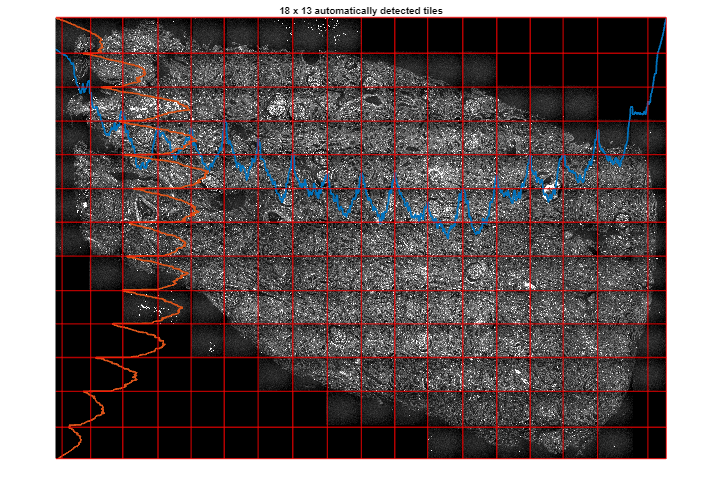

[nRows, nCols] = size(img);
scaledRowIntensity = (avgRowIntensity - min(avgRowIntensity)) / (max(avgRowIntensity)-min(avgRowIntensity)) * nRows;
scaledColIntensity = (avgColIntensity - min(avgColIntensity)) / (max(avgColIntensity)-min(avgColIntensity)) * nCols;
figure;
hImg = imshow(imadjust(img - mean([min(avgRowIntensity), min(avgColIntensity)])/1.5));
axis equal tight; hold on;
plot(1:nCols, scaledRowIntensity/2, '-', 'LineWidth', 2);
plot(scaledColIntensity/4, 1:nRows, '-', 'LineWidth', 2);
set(gca, 'YDir', 'reverse');
xlim([1, nCols]); ylim([1, nRows]);
% Estimate standard tile edge locations using linspace and detected peaks.
numTileCols = round(nCols / (1/domRowFreq));
numTileRows = round(nRows / (1/domColFreq));
stdEdgeLocsX = linspace(1, nCols, numTileCols+1);
stdEdgeLocsY = linspace(1, nRows, numTileRows+1);
[~, detectedEdgesX] = findpeaks(-scaledRowIntensity, 'MinPeakDistance', 0.8*(1/domRowFreq));
[~, detectedEdgesY] = findpeaks(-scaledColIntensity', 'MinPeakDistance', 0.8*(1/domColFreq));
edgelocsX = round(matchEdgeLocations(stdEdgeLocsX, detectedEdgesX));
edgelocsY = round(matchEdgeLocations(stdEdgeLocsY, detectedEdgesY));
xline(edgelocsX, 'r-', 'LineWidth', 1.5);
yline(edgelocsY, 'r-', 'LineWidth', 1.5);
title(num2str(numTileCols) + " x " + num2str(numTileRows) + " automatically detected tiles");

## Find the general vignetting correction for the uniform case

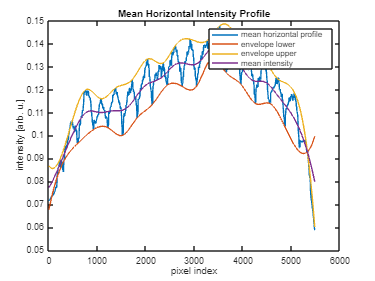

%%%%%%% Horizontal correction
figure
plot(avgRowIntensity)
hold on
[l,h]=envelope(avgRowIntensity,round(0.8*(1/domRowFreq)),'peak');
plot(h)
plot(l)
ideallineRow=mean([l;h]);
plot(ideallineRow)
title("Mean Horizontal Intensity Profile")
xlabel("pixel index")
ylabel("intensity [arb. u.]")
legend({'mean horizontal profile','envelope lower','envelope upper','mean intensity'});
hold off

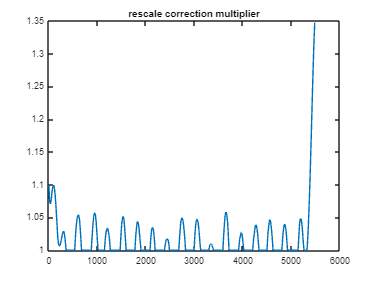


rescalefactorx=ideallineRow./avgRowIntensity;
rescalefactorx=sgolayfilt(rescalefactorx,5,2*round((1/(2*domRowFreq)))+1);
rescalefactorx(rescalefactorx<1)=1; % Multiplies all pixels in the rows that are darker than the midpoint so that they become the midpoint.

figure
plot(rescalefactorx)
title("rescale correction multiplier")

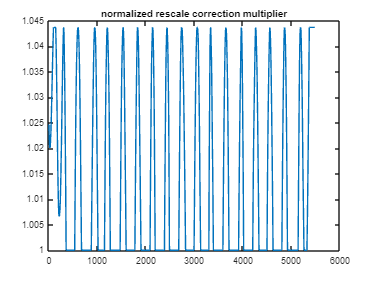

[l,h]=envelope(rescalefactorx,round(0.6*(1/domRowFreq)),'peak');
[pks,locs]=findpeaks(rescalefactorx);

envrng=l-1;
neworiginal=rescalefactorx-1;
envnorm=neworiginal./envrng;
rescalefactorx=1+envnorm.*(mean(pks)-1);
rescalefactorx(rescalefactorx>mean(pks))=mean(pks);
plot(rescalefactorx)
title("normalized rescale correction multiplier")

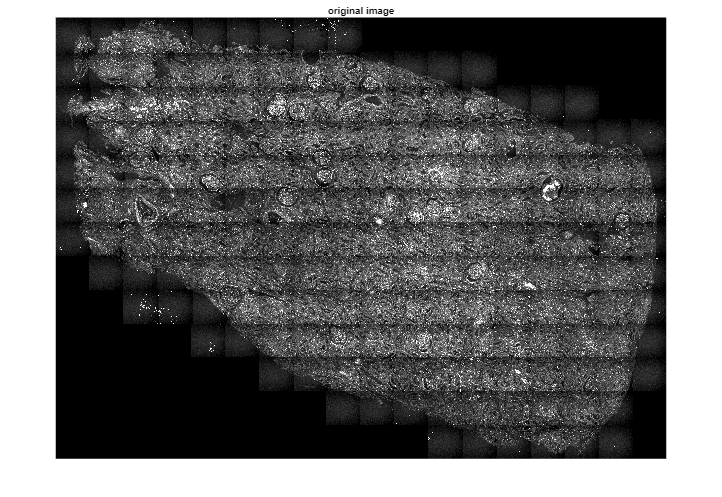


newhorzimg=img.*(rescalefactorx.^2);
newhorzimg(img==0)=0;
figure
imshow(imadjust(img))
title("original image")

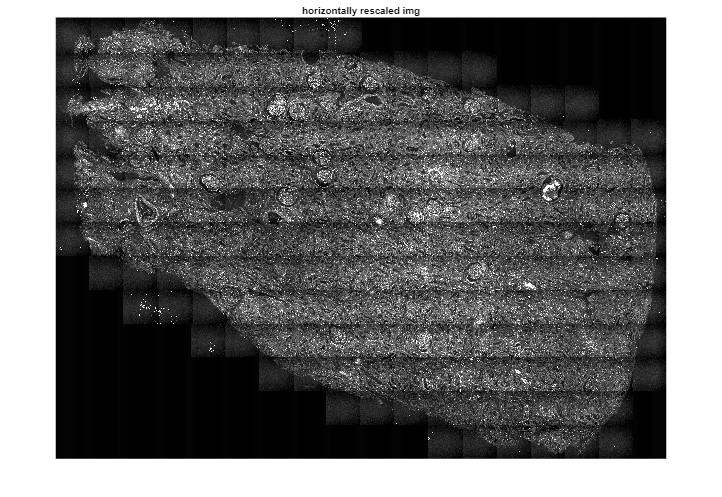

figure
imshow(imadjust(newhorzimg))
title("horizontally rescaled img")

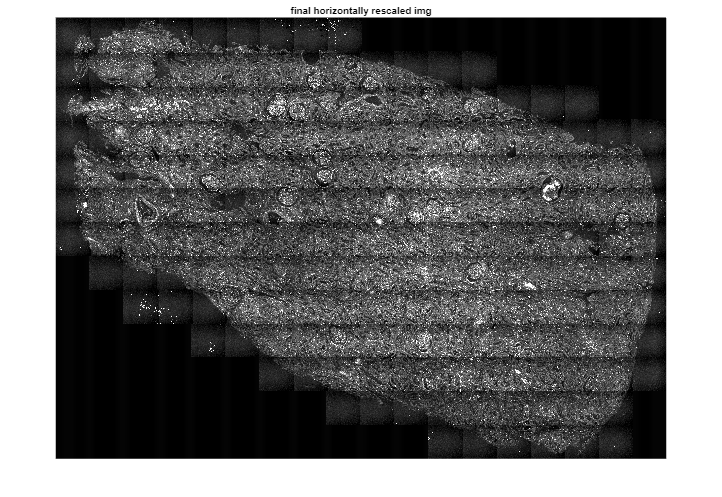

% we brought up the troughs, now we need to attenuate the peaks (bright
% spots) a little bit
brightspots=(avgRowIntensity-ideallineRow)+1;
brightspots=sgolayfilt(brightspots,5,2*round((1/(2*domRowFreq)))+1);
brightspots(brightspots<=1)=1;
brightspots(brightspots>1)=0.99;
B = smoothdata(brightspots,'gaussian');
brightadjust=max([brightspots;B]);
newhorzimg=newhorzimg.*(brightadjust);
newhorzimg(img==0)=0;
figure
imshow(imadjust(newhorzimg))
title("final horizontally rescaled img")

% Sample the original image for the background intensity (not the empty NaN pixels)
% Flatten the 2D array to a 1D array and remove NaN values
pixels = imgNaN(~isnan(imgNaN));
pixels = pixels(:); % Ensure it's a column vector

% Calculate the threshold for the bottom 1% of the pixels
thresholdValue = prctile(pixels, 1);

% Find the pixels in the bottom 1% and calculate their mean
bottom1PercentPixels = pixels(pixels <= thresholdValue);
meanBottom1Percent = mean(bottom1PercentPixels)

meanBottom1Percent = 0.0537

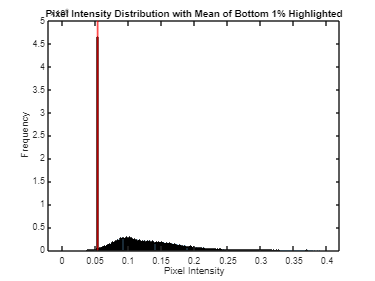


% Plot the histogram of the pixel intensities
figure;
histogram(pixels, 256); % Adjust the number of bins as necessary
hold on; % Keep the histogram on the plot

% Add a vertical line at the mean value of the bottom 1%
xline(meanBottom1Percent, 'r', 'LineWidth', 2);

% Labels for clarity
xlabel('Pixel Intensity');
ylabel('Frequency');
title('Pixel Intensity Distribution with Mean of Bottom 1% Highlighted');
hold off;

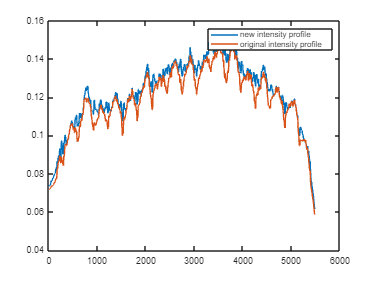


% create background image as a baseline
[r,c]=size(img);
bgimg=repmat(meanBottom1Percent,r,c);
% manipulate the bgimg like the first image with the troughs
newhorzbgimg=bgimg.*(rescalefactorx.^2);
bgsubtract=newhorzbgimg-bgimg; %maybe add gaussian blur to the bgsubtract
bgsubtract(img == 0) = 0;
newhorzimg=newhorzimg-0.5*bgsubtract;




%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Finally, let's plot the intensity profile again to see if it's better
imgNaN2=newhorzimg;
imgNaN2(imgNaN2 == 0) = NaN;
newavgRowIntensity = medfilt1(mean(imgNaN2, 1, 'omitnan'),10);
newavgRowIntensity(1)=newavgRowIntensity(2);
figure
plot(newavgRowIntensity)
hold on
plot(avgRowIntensity)
legend({'new intensity profile','original intensity profile'})

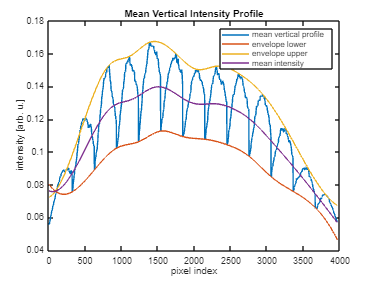


%%%%%%%%%%%%%%%%%%%%%% repeat for columns%%%%%%%%%%%%%%%%%
figure
plot(avgColIntensity)
hold on
[l,h]=envelope(avgColIntensity,round(0.8*(1/domColFreq)),'peak');
plot(h)
plot(l)
ideallineCol=mean([l';h']);
plot(ideallineCol)
title("Mean Vertical Intensity Profile")
xlabel("pixel index")
ylabel("intensity [arb. u.]")
legend({'mean vertical profile','envelope lower','envelope upper','mean intensity'});
hold off

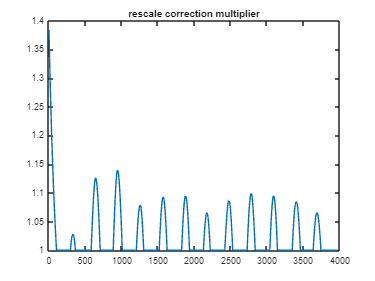


rescalefactory=ideallineCol./avgColIntensity';
rescalefactory=sgolayfilt(rescalefactory,5,2*round((1/(2*domColFreq)))+1);
rescalefactory(rescalefactory<1)=1; % Multiplies all pixels in the rows that are darker than the midpoint so that they become the midpoint.

figure
plot(rescalefactory)
title("rescale correction multiplier")

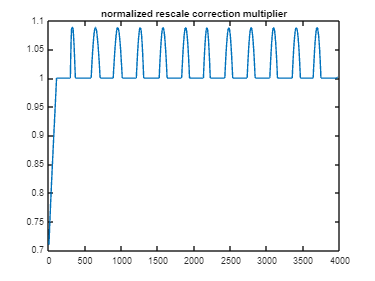

[l,h]=envelope(rescalefactory,round(0.6*(1/domColFreq)),'peak');
[pks,locs]=findpeaks(rescalefactory);

envrng=l-1;
neworiginal=rescalefactory-1;
envnorm=neworiginal./envrng;
rescalefactory=1+envnorm.*(mean(pks)-1);
rescalefactory(rescalefactory>mean(pks))=mean(pks);
plot(rescalefactory)
title("normalized rescale correction multiplier")

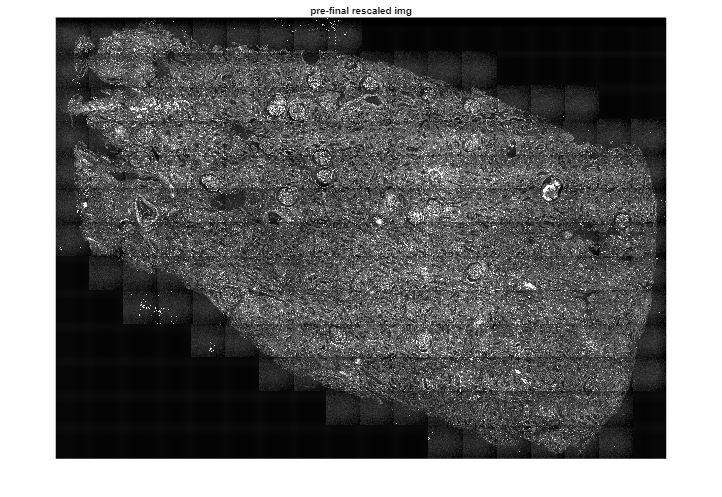


rescalefactory=rescalefactory';
newvertimg=newhorzimg.*(rescalefactory.^2);
newvertimg(img==0)=0;

brightspots=(avgColIntensity-ideallineCol')+1;
brightspots=sgolayfilt(brightspots,5,2*round((1/(2*domColFreq)))+1);
brightspots(brightspots<=1)=1;
brightspots(brightspots>1)=0.99;
B = smoothdata(brightspots,'gaussian');
brightadjust=max([brightspots';B']);
newvertimg=newvertimg.*(brightadjust');
newvertimg(img==0)=0;


newvertbgimg=bgimg.*(rescalefactory.^2);
bgsubtract=newvertbgimg-bgimg; %maybe add gaussian blur to the bgsubtract
bgsubtract(img == 0) = 0;
newvertimg=newvertimg-0.5*bgsubtract;

figure
imshow(imadjust(newvertimg))
title("pre-final rescaled img")

finalImg=newvertimg;


## Continue if not satisfied:

## Re-mask with thresholded TPF image to remove background pixels (because usually the vignetting is caused by poor beam-condenser-photodiode alignment)

You can do this is imagej/FIJI by opening an image, then CTRL+Shift+T then manually identifying where the tissue is (will be automated in the future) and then click "apply" and save it as a TIF image

Then proceed below 

%user defines the save file name

defaultsavename=strcat("flat_",extractBetween(fname,1,'.'));
[fnamesave, fpathsave]=uiputfile('*.tif','Save your image',defaultsavename);


% Ask if a pre-made tissue mask exists to refine the correction.
userResponse = questdlg('Do you already have a tissue mask?', ...
    'Optional Tissue Isolation', ...
    'Yes', 'No', 'do not isolate', 'Yes');

switch userResponse
    case 'Yes'
        [maskName, maskPath] = uigetfile({'*.tif;*.tiff'}, 'Select Mask Image', 'MultiSelect', 'off');
        mask = imread(fullfile(maskPath, maskName));
        mask = rescale(mask);
        mask = imgaussfilt(double(mask), 2);
        finalImg = finalImg .* mask;
        
    case 'No'
        % Recompute a tissue mask from finalImg using similar steps as above.
        nonZeroFinal = finalImg(finalImg ~= 0);
        sortedFinal = sort(nonZeroFinal);
        numEltsFinal = round(0.01 * numel(sortedFinal));
        if numEltsFinal > 0
            threshFinal = sortedFinal(numEltsFinal);
        else
            threshFinal = sortedFinal(1);
        end
        finalImg(finalImg == 0) = threshFinal;
        figure; imshow(imadjust(rescale(finalImg)));
        
        % Morphological operations to isolate tissue.
        seDiskFinal = strel('disk', 50);
        closedFinal = imclose(finalImg, seDiskFinal);
        openKernelFinal = strel('disk', round(0.01 * size(finalImg, 1)));
        openedFinal = imopen(closedFinal, openKernelFinal);
        openedFinal = rescale(openedFinal);
        figure; imshow(imadjust(openedFinal));
        
        tissueMaskBin = imbinarize(openedFinal, 0.1);
        seMaskFinal = strel('disk', round(0.05 * size(finalImg, 1)));
        tissueMaskBin = imclose(tissueMaskBin, seMaskFinal);
        tissueMaskBin = imfill(tissueMaskBin, 'holes');
        figure; imshow(tissueMaskBin);
        bgPixelFinal = find(~tissueMaskBin);
        cutoff1 = mean(finalImg(bgPixelFinal));
        cutoff2 = prctile(finalImg(:), 90);
        combinedCutoffFinal = 1.05 * mean([cutoff1; cutoff2]);
        mask = finalImg;
        mask(mask < combinedCutoffFinal) = 0;
        mask(mask >= combinedCutoffFinal) = 1;
        figure; imshow(mask);
        mask = imgaussfilt(double(mask), 2);
        finalImg = finalImg .* mask;
        
    case 'do not isolate'
        % Do nothing; proceed without applying an external tissue mask.
end

## Now use line opening and closing to find finishing touches to get homogeneity

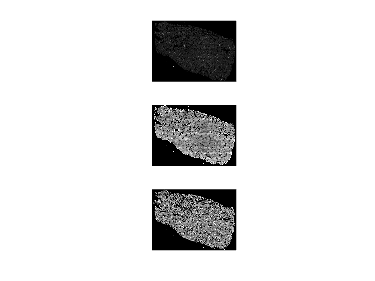

A=finalImg;
A=double(rescale(A));
ImageWithoutPoints = A-imtophat(A,strel('disk',50)).*(imtophat(A,strel('disk',50))>1000);

IlluminationImage = imopen(imclose(ImageWithoutPoints,strel('line',50,0)), strel( 'line',50,0));

Result = uint16((double(ImageWithoutPoints) ./double(IlluminationImage)).*50000);

Result=double(Result).*mask;%%%%%%%%%%

divimage=rescale(Result)./A; %%%%%%%%%%%%%%%%%


figure
subplot(3, 1, 1);  % "before" image
imshow(A);

subplot(3, 1, 2);  % what it needs to be multiplied with 
imshow(imadjust(rescale(divimage)));

subplot(3, 1, 3);  % morphologically flat image
imshow(imadjust(rescale(Result)));

## Use the rowint and colint to apply a line structuring element filter

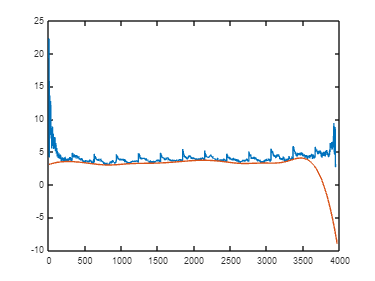

% Set pixels to NaN where the mask is 0
image_with_nan = divimage;  % Copy the original image
image_with_nan(mask == 0) = NaN;  % Replace pixels with NaN based on the mask



% Calculate the mean of each column, ignoring NaNs
column_means = nanmean(image_with_nan, 2);  % column vector of row means

% Transpose the result to get a column vector
column_means = column_means';
% Find indices where column_means is not NaN
idx = 1:length(column_means);
validIdx = ~isnan(column_means);

% Interpolate to fill in NaN values using 'pchip'
column_means_filled = interp1(idx(validIdx), column_means(validIdx), idx, 'pchip');

% Now calculate the envelope using the filled vector.
windowSize = round(0.75 * (1/domColFreq));  % colint is your predetermined interval
[l, h] = envelope(column_means_filled, windowSize, 'peak');

%[l,h]=envelope(column_means,round(0.75*(1/colint)),'peak');

figure
plot(column_means);
hold on
plot(h)
hold off

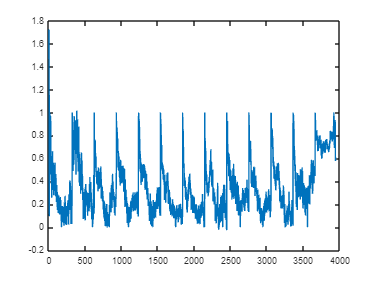



waveform=column_means;
normalized_waveform = (waveform - h) ./ (l - h);
plot(normalized_waveform);

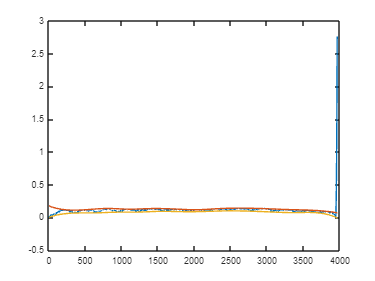

getrangeimg=A;
getrangeimg(mask==0)=NaN;
prerange=nanmean(getrangeimg,2);
prerange = interp1(idx(validIdx), prerange(validIdx), idx, 'pchip');
[lowprerange, highprerange]=envelope(prerange,round(0.75*(1/domColFreq)),'peak');

figure
plot(prerange);
hold on
plot(lowprerange);
plot(highprerange);
hold off

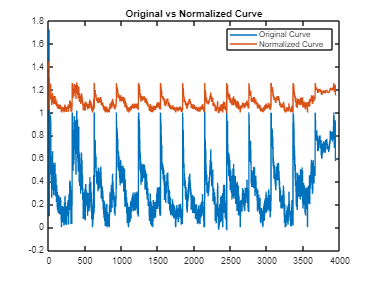

prcincrease=lowprerange./highprerange;
n = length(prcincrease); % replace 'your_vector' with your actual vector name

% Determine the range for the middle half
start_idx = floor(n / 4) + 1;
end_idx = ceil(3 * n / 4);

% Extract the middle half of the vector
middle_half = prcincrease(start_idx:end_idx);

% Calculate the mean of the middle half
middle_half_mean = mean(middle_half);
% Assume 'your_curve' is the curve you want to normalize
min_value = 0; % Find the minimum of the curve
max_value = max(normalized_waveform); % Find the maximum of the curve

% Normalize the curve
normalized_curve = (normalized_waveform - min_value) / (max_value - min_value); % Scale to [0, 1]
normalized_curve = normalized_curve * (middle_half_mean - 1) + 1; % Scale to [1, middle_half_mean]



% Optional: Plot the original and normalized curves
figure;
plot(normalized_waveform, 'DisplayName', 'Original Curve');
hold on;
plot(normalized_curve, 'DisplayName', 'Normalized Curve');
legend;
title('Original vs Normalized Curve');

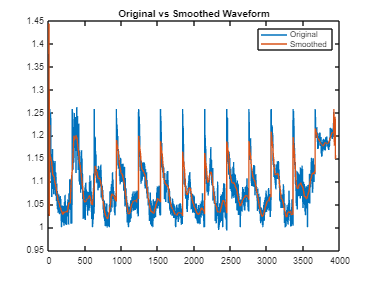

% Example waveform

y = normalized_curve; % replace with your actual waveform data

% Find the peaks
[peaks, locs] = findpeaks(y,'minpeakdistance',0.8*(1/domRowFreq));

% Initialize smoothed waveform
y_smoothed = y;

% Smoothing only the decay side of each peak
for i = 1:length(locs)-1
    % Define the decay region after each peak
    decay_region = locs(i):locs(i+1)-1;
    
    % Apply a smoothing filter (e.g., moving average)
    y_smoothed(decay_region) = smoothdata(y(decay_region), 'movmean', 51); % Adjust the window size as needed
end

% Plot the original and smoothed waveform
figure;
plot( y, 'DisplayName', 'Original');
hold on;
plot( y_smoothed, 'DisplayName', 'Smoothed');
legend;
title('Original vs Smoothed Waveform');

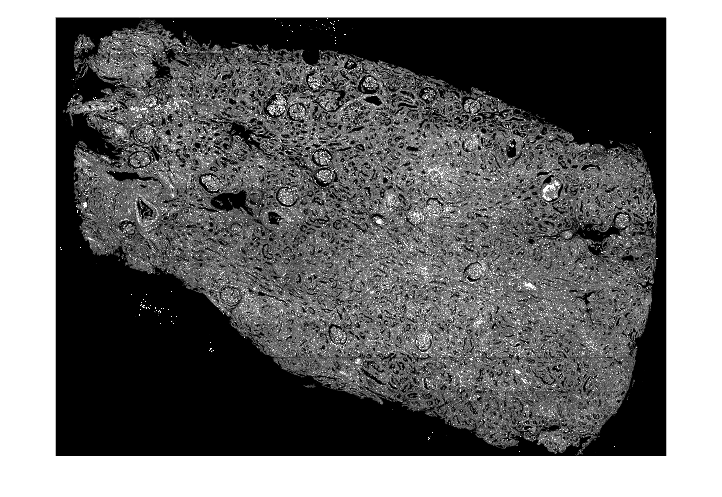

y_smoothed_matrix = repmat(y_smoothed', 1, size(finalImg, 2));
finalfinalimg=finalImg.*y_smoothed_matrix;
%finalfinalimg=rescale(finalfinalimg).*normorigrange;
finalfinalimg(brightspotsstore~=0)=brightspotsstore(brightspotsstore~=0);
figure
imshow(imadjust(rescale(finalfinalimg)))

imwrite(im2uint16(rescale(finalfinalimg)),fullfile(fpathsave,strcat('final_',fnamesave)),'tif')


## Helper Functions

function [domRowFreq, domColFreq, freqRow, magRow, freqCol, magCol] = detectDominantFrequencies(rowProfile, colProfile)
    % detectDominantFrequencies computes FFTs for row and column intensity profiles,
    % returning dominant frequencies and their frequency axes and magnitudes.
    
    % FFT on column (vertical) profile.
    fftRow = fft(rowProfile);
    nRow = length(rowProfile);
    freqRow = (0:nRow-1) / nRow;
    halfIdxRow = 1:floor(nRow/2)+1;
    magRow = abs(fftRow/nRow);
    magRow(2:end-1) = 2 * magRow(2:end-1);
    freqRow = freqRow(halfIdxRow);
    magRow = magRow(halfIdxRow);
    % Find dominant frequency in row profile.
    [peaksRow, locsRow] = findpeaks(magRow);
    [~, idxRow] = max(peaksRow);
    domRowFreq = freqRow(locsRow(idxRow));
    
    % FFT on row (horizontal) profile.
    fftCol = fft(colProfile);
    nCol = length(colProfile);
    freqCol = (0:nCol-1) / nCol;
    halfIdxCol = 1:floor(nCol/2)+1;
    magCol = abs(fftCol/nCol);
    magCol(2:end-1) = 2 * magCol(2:end-1);
    freqCol = freqCol(halfIdxCol);
    magCol = magCol(halfIdxCol);
    [peaksCol, locsCol] = findpeaks(magCol);
    [~, idxCol] = max(peaksCol);
    domColFreq = freqCol(locsCol(idxCol));
end

function matchedEdges = matchEdgeLocations(stdEdges, detectedEdges)
    % Ensure stdEdges is a column vector and detectedEdges is a row vector
    stdEdges = stdEdges(:);
    detectedEdges = detectedEdges(:).';
    
    % Compute the absolute differences between each pair of standard and detected edges
    diffMat = abs(bsxfun(@minus, stdEdges, detectedEdges));
    
    % Set a threshold based on half the average spacing of standard edges
    threshold = 0.5 * mean(diff(stdEdges));
    valid = diffMat < threshold;
    
    % Initialize the output vector with NaNs
    matchedEdges = nan(size(stdEdges));
    
    % For each standard edge, average the detected edges that fall within the threshold
    for k = 1:length(stdEdges)
        if any(valid(k, :))
            matchedEdges(k) = mean(detectedEdges(valid(k, :)));
        end
    end
    
    % Replace any unmatched edges with the original standard edge value
    matchedEdges(isnan(matchedEdges)) = stdEdges(isnan(matchedEdges));
end
